# **IO619 - MVB Loopback**

This example shows you how to perform a loopback test with two IO619 MVB I/O modules, to verify the basic protocol communication over the **Multifunction Vehicle Bus (MVB)**.

The IO619 I/O module is an intelligent MVB / WTB module with Simulink® driver blocks. An independent MVB bus controller provides low-level message handling.

The Simulink model features the [IO619 MVB Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io619_setup) and [IO619 Process Data](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io619_process_data) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with two IO619 I/O module installed

- DSUB-9 connector cable

- Termination for the MVB bus ends

### Test Setup

In this example, data is sent from one IO619, configured as bus administrator, to a second I/O module, configured as a MVB node. You must therefore connect one port of the first IO619 with one port of the second IO619 (Note: Do not use crossed/Null modem DSUB-9 cables). 

Each IO619 can be replaced with an external MVB device in case only one IO619 is available in your real-time target machine. Check the model and the configuration file for the used messages and their configuration.

Attach the MVB bus termination to the other port of the IO619 (Note: The termination setup varies depending on the specific version of the IO619, as either ESD or EMD versions are available).

See below an example of an EMD bus setup:

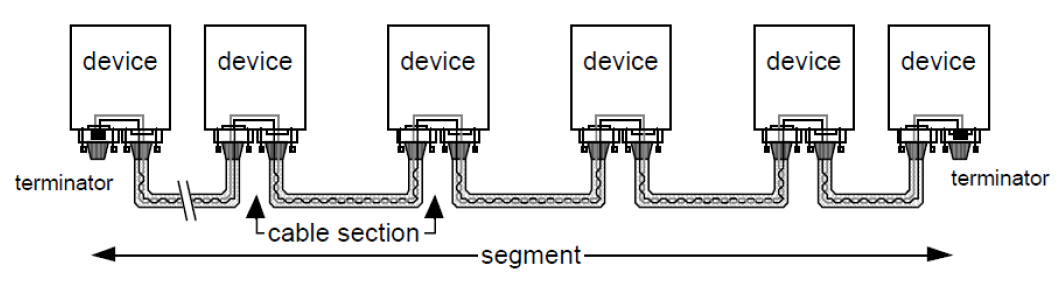

For the detailed pin mapping on the D-Sub9 connector please refer to the [IO619 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io619_pin_mapping) in the documentation. 

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO619_MVBLoopback';
open_system(modelName);

### Model Description

In the model, a sine wave signal gets packed into a byte data stream with a [Byte Packing](https://www.mathworks.com/help/slrealtime/io_ref/bytepacking.html) block to be transmitted by the [IO619 Process Data](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io619_process_data) block. On the receiving side, the data gets unpacked to retrieve the original signal with a [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block. The **Freshness** output shows if the last valid reception of the message has happened in the configured port cycle time. The port cycle time is specified in the bus administrator configuration file. The **Freshness** output can as well be changed in the block mask to show the elapsed time since the last valid reception in milliseconds.

All the necessary parameters for the bus administrator are saved in an external configuration file, that is available in this example. (MVB_baConfig.csv)

The address, size and sample time from the [IO619 Process Data](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io619_process_data) block must match the ones specified in the configuration file.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check that the loopback is working as expected, open the Simulink scope connected to the [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block. In the scope, a sine wave signal must be displayed, and the freshness indicator (represented by a straight blue line):

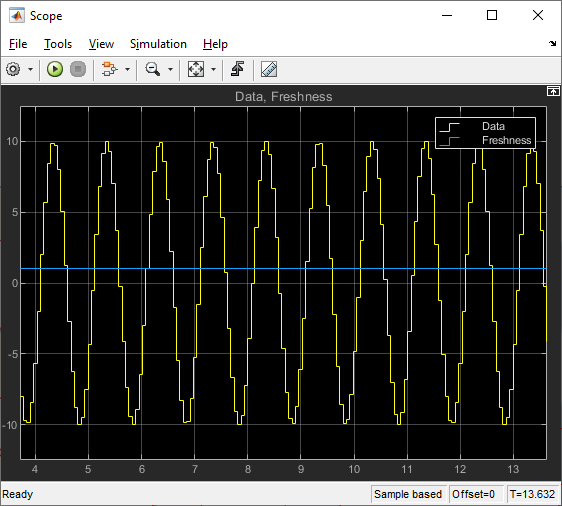

## Additional References

- [IO619 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io619)